clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw

dx_new = 1.8750e-04

w = 1500/1e6%1.5mm

w = 0.0015

p = wavelength/dx

p = 37500


%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,7e-5);%128SQRT2/1500
t_array_new = Kgrid.t_array(1:126)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960



% define a single source point
source.p_mask = zeros(Nx, Ny);
source_x1 = 70/120*Nx;
source_x2 = 100/120*Nx;
source_y1 = Ny/2

source_y1 = 225

source.p_mask(source_x1, source_y1) = 1;
source.p_mask(source_x2, source_y1) = 1;
% source_x = 70/120*Nx;
% 
% source_y1 = Ny/2+7;
% source_y2 = Ny/2-7;
% source.p_mask(source_x, source_y1) = 1;
% source.p_mask(source_x, source_y2) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
%% 

% filter the source to remove high frequencies not supported by the grid
%source.p = filterTimeSeries(Kgrid, medium, source.p);

%define the sensor in a line
x_offset = 20/120*Nx % [grid points]

x_offset = 100

width = 50/90*Ny% [grid points]

width = 250

sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

Running k-Wave simulation...
  start time: 10-Sep-2023 23:02:31
  reference sound speed: 1500m/s
  dt: 40ns, t_end: 70us, time steps: 1751
  input grid size: 600 by 450 grid points (120 by 90mm)
  maximum supported frequency: 3.75MHz
  precomputation completed in 0.18558s
  starting time loop...
  estimated simulation time 1min 2.6858s...


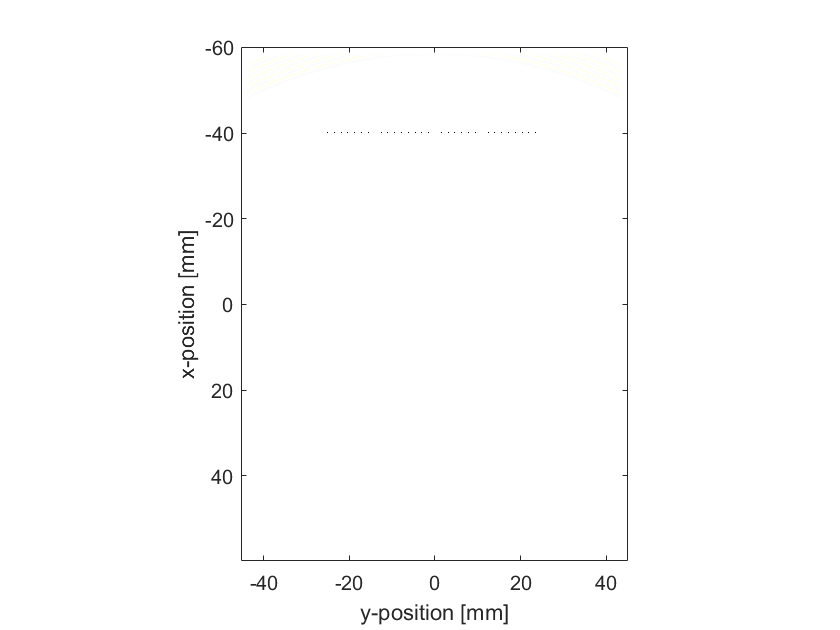

  simulation completed in 1min 10.5523s
  total computation time 1min 10.77s




% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);

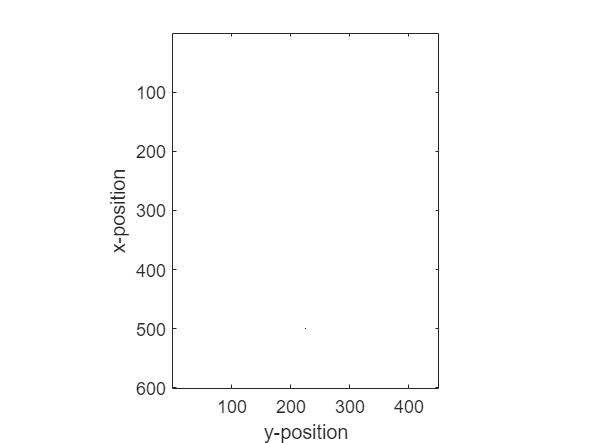




% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

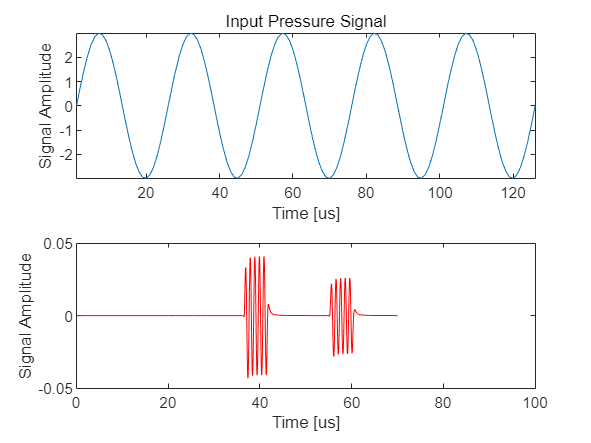

%% 


% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);

%axis tight;
%axis([0,10.5,-inf,inf]);



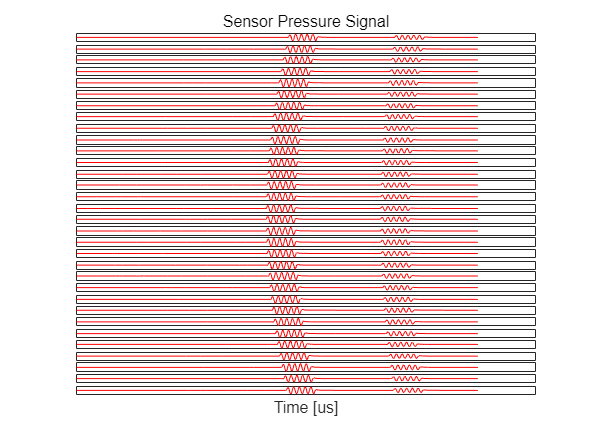


%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4
% Kgrid.t_array
% t_array_limit = 1/source_freq*5
% t_array_new = Kgrid.t_array(1:32)
% 1/2E-4
% 128*1.414/1500



tic
%obtian all the sensor position
sensorpoistion = zeros(1,32);
j=1;
for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
% sensorpoistion()
tlength = Kgrid.t_array(1:126);
%distance from sensor to source mm
distance_map = zeros(1,32);
% intensitymap = zeros(1,1600);
%sourceposition =[70/120*Nx, Ny/2]%x=350,y=225
distance = zeros(1,32);
for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end


%all the source position

%Create a 20mm times 20mm grid, which is 200 times 200
%x from 
map_length = zeros(1,300);
map_width = zeros(1,300);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2

for i = 1:300
    map_length(i)=(source_x1+source_x2)/2-150+i;
    map_width(i)=225-150+i;
end
% map_length
% map_width
%x = 350-map_width:350+map_width
%y = 225-map_width:225+map_width


%the intensity map position
%map_width = 40/120*Nx;
%map = zeros(map_width,map_width);

%store the map postion
%coeff = 4/32*pi;
step = zeros(1,32);
%timespan = 1501;
timespan = length(Kgrid.t_array);
sensor_data_test = zeros(32,timespan);
sensor_data_new = zeros(32,timespan);
%times distance with the sensor data3m

%define the energy map
energymap = zeros(300,300);

%ratio of the coherent sum to the incoherent sum


%distance from sensor to source mm
%distance_map = zeros(1,32);
%the map
% intensitymap = zeros(1,1600);
for m = 1:300
     for n = 1:300
         A = zeros(32,timespan);
        for i = 1:32
            %calculate distance from each point
            distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            timeshift = distance_map*dx/c;

            
            %apply the time delay to the sensor data
            step(i) = floor(timeshift(i)/4e-8);
            sensor_data_test(i,:) = sensor_data(i,:);
            sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
            A(i,:) = sqrt(distance_map(i))*sensor_data_new(i,:);
        end
        %sum 32 sensor data together
        sum_A = sum(A);
        
        %coherent sum
        Co_SUM =  sum_A.^2;

        %incoherent sum
        INCO_SUM = 32*sum(A.^2);
    
        %coherence-factor
        CF = Co_SUM/INCO_SUM;

        %INTENSITY
        %intensity = coeff * sum_A;
        intensity= CF*sum_A;
        %intensity= sum_A;



        %integral'
        intensity_2 = intensity.^2;
        intensity_2_int = intensity_2(1:126);
        Q = trapz(intensity_2_int);
        %coeff2 = 1/(4*pi*1500);
%         energymap(n,m)= intensity_2*intensity_2'/32/32*coeff2;
        %energymap(n,m)= Q*coeff2;
        energymap(n,m)= Q;
     end
end



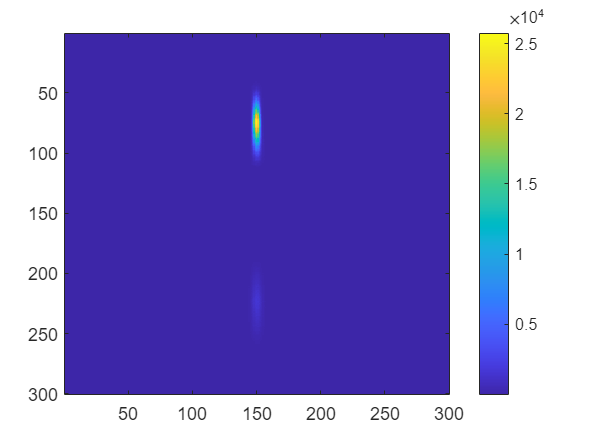

figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例

toc

历时 49.650318 秒。


    
%normalize image
min_value = min(min(energymap))

min_value = 4.0076e-08

max_value = max(max(energymap))

max_value = 2.5739e+04

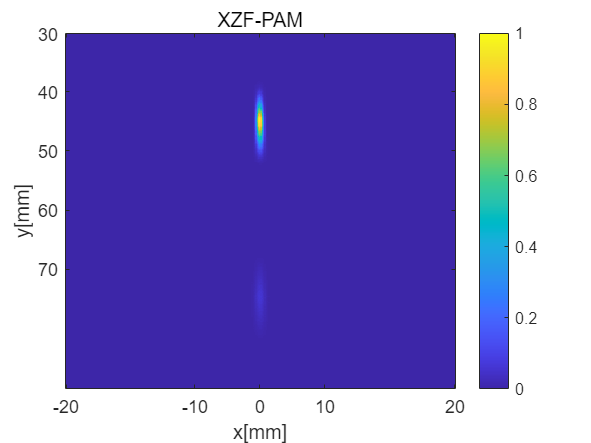

normalized_array = (energymap - min_value) / (max_value - min_value);
imagesc(normalized_array);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例
x_ticks = [1,100,150,200,300];
x_tick_labels = {-20,-10,0,10,20};
xticks(x_ticks);
xticklabels(x_tick_labels);

y_ticks = [1,50,100,150,200];
y_tick_labels = {30,40,50,60,70};
yticks(y_ticks);
yticklabels(y_tick_labels);
xlabel(['x[mm]']);
ylabel('y[mm]');

title('XZF-PAM');

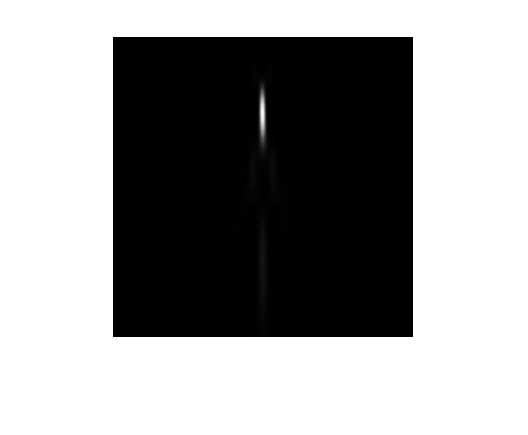

figure
imshow(energymap,[])

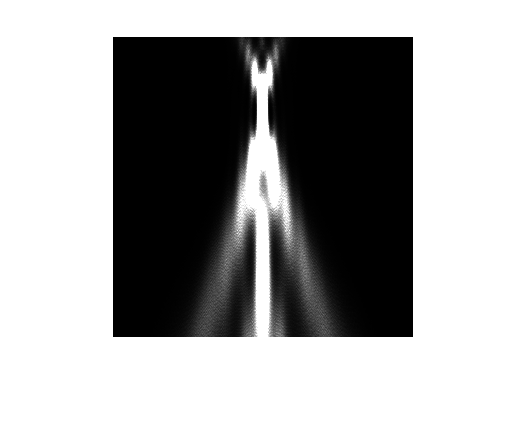


figure

%imshow(energymap/256)

imshow(uint8(energymap))


rea = im2uint8(mat2gray(energymap));


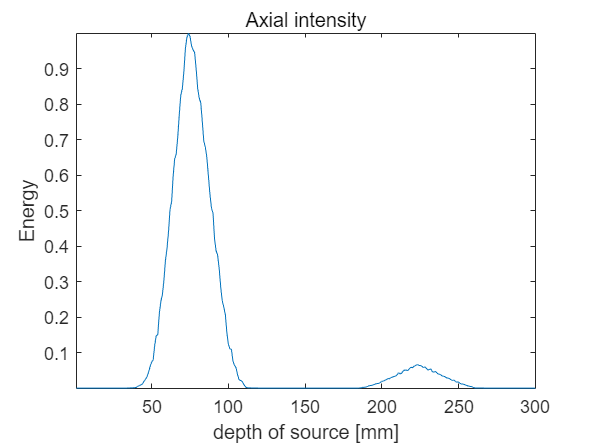


%axial resolution
%index = 30:0.2:69.8;
axial = zeros(1,300);
for i = 1:300
    axial(i)= normalized_array(i,150);
end

% plot the value
figure;
%[t_sc, scale, prefix] = scaleSI(max(map_length));


plot(axial)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['depth of source [mm]']);
ylabel('Energy');
axis ([-inf,inf,-inf,inf]);
title('Axial intensity');


% left value
leftEdge = find(axial >= 0.5*max(axial), 1, 'first')

leftEdge = 62


% right value
rightEdge = find(axial >= 0.5*max(axial), 1, 'last')

rightEdge = 89


% width
fwhmWidth = (rightEdge - leftEdge);

% 打印 FWHM 宽度
fprintf('FWHM width: %.2f mm', fwhmWidth);

FWHM width: 27.00 mm

center_axial = find(axial == max(axial),1)

center_axial = 74

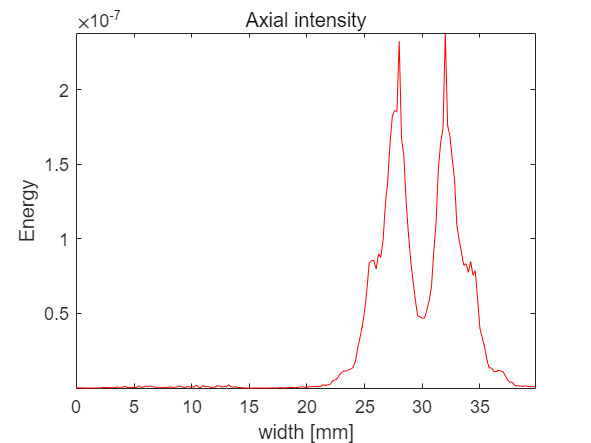


%lateral resolution
index = 0:0.2:39.8;
lateral = zeros(1,200);
for i = 1:200
    lateral(i)= normalized_array(150,i);
end

% plot the value
figure;
[t_sc, scale, prefix] = scaleSI(max(map_width));


plot(index,lateral,'r-')
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['width [mm]']);
ylabel('Energy');
axis ([-inf,inf,-inf,inf]);
title('Axial intensity');


% left value
leftEdge = find(lateral >= 0.5*max(lateral), 1, 'first')

leftEdge = 135


% right value
rightEdge = find(lateral >= 0.5*max(lateral), 1, 'last')

rightEdge = 165


% width
fwhmLength = (rightEdge - leftEdge);

% 打印 FWHM 宽度
fprintf('FWHM width: %.2f mm', fwhmLength);

FWHM width: 30.00 mm

center_lateral = find(lateral == max(lateral),1)

center_lateral = 161

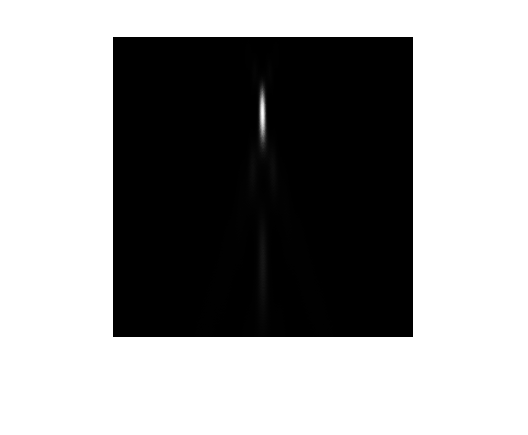


figure
imshow(rea)


%source strength = 4pi/N*sum(distance*signal)

coeff = 4/32*pi

coeff = 0.3927

%distance_total = sum(distance, 'all')

%apply the time delay to the sensor data
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


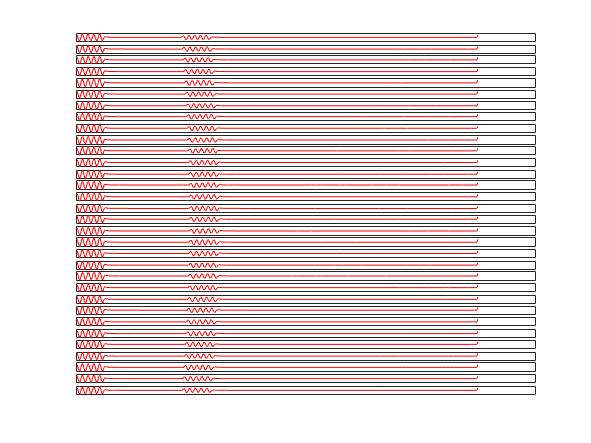

sensor_data_test = zeros(32,timespan);
sensor_data_new = zeros(32,timespan);
tj = distance*dx/c;
for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end

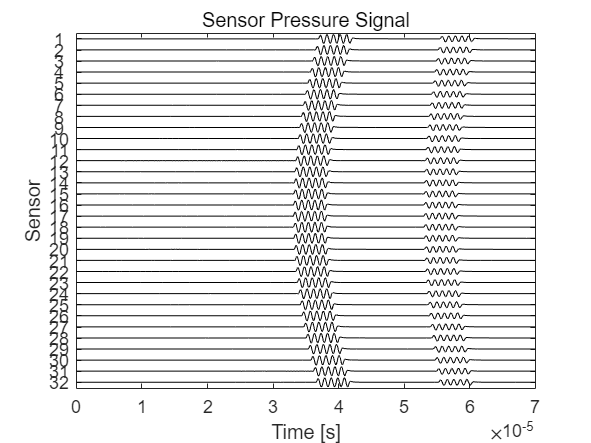




figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

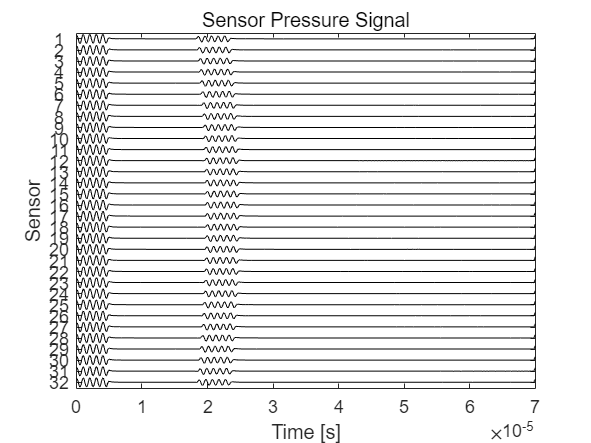


figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');



%calculate intensity
figure
A = zeros(32,timespan)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

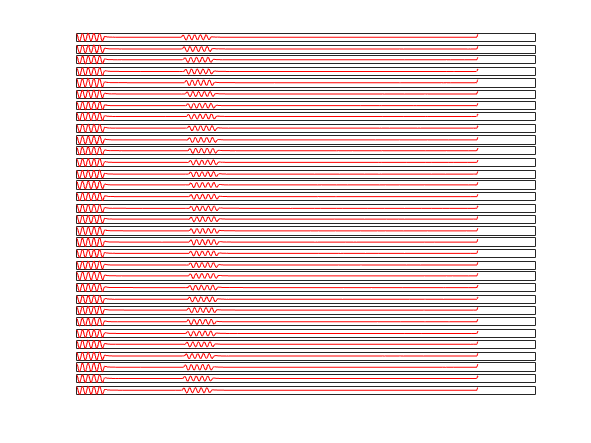

A(1,:) = distance(1)*sensor_data_new(1,:);
for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end



figure
sum_A = sum(A)

sum_A =   274.2312  290.9321  287.3371  262.7697  218.2379  156.2750   80.7948   -3.1732  -89.9222 -173.5951 -248.6605 -310.2510 -354.3759 -378.0890 -379.6654 -358.7721 -316.5591 -255.6068 -179.7211  -93.6300   -2.6524   87.6184  171.6192  244.1293  300.6007  337.4799  352.4691  344.6847  314.6919  264.4348  197.0918  116.8829   28.8342  -61.5087 -148.4235 -226.3916 -290.4768 -336.6514 -362.0373 -365.0554 -345.5006 -304.5562 -244.7471 -169.8114  -84.4737    5.8742   95.5444  178.9279  250.8324  306.7762



%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A

intensity =   107.6903  114.2488  112.8370  103.1894   85.7018   61.3690   31.7281   -1.2461  -35.3124  -68.1706  -97.6488 -121.8353 -139.1631 -148.4752 -149.0943 -140.8895 -124.3125 -100.3766  -70.5763  -36.7684   -1.0416   34.4077   67.3947   95.8693  118.0456  132.5280  138.4143  135.3574  123.5792  103.8433   77.3978   45.8998   11.3232  -24.1544  -58.2858  -88.9038 -114.0700 -132.2027 -142.1717 -143.3569 -135.6778 -119.5989  -96.1119  -66.6848  -33.1727    2.3068   37.5202   70.2648   98.5017  120.4707


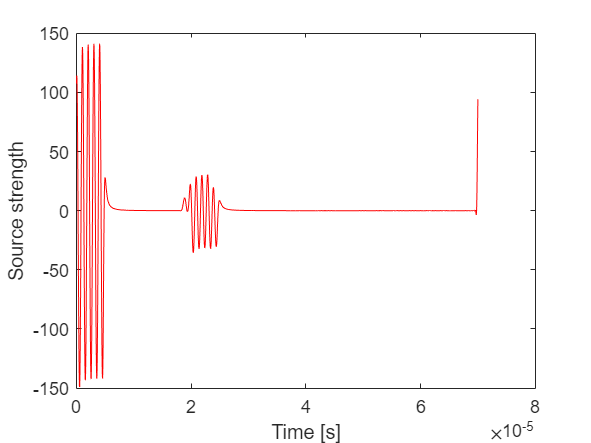

plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');



%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)

Q = 1.2830e+06

coeff2 = 1/(4*pi*1500)

coeff2 = 5.3052e-05

%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff2*sum(A)).^2

fun = 包含以下值的 function_handle :
    @(x)(coeff2*sum(A)).^2


%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)

q = 1.0e-07 *

    0.1058    0.1191    0.1162    0.0972    0.0670    0.0344    0.0092    0.0000    0.0114    0.0424    0.0870    0.1355    0.1767    0.2012    0.2028    0.1811    0.1410    0.0919    0.0455    0.0123    0.0000    0.0108    0.0414    0.0839    0.1272    0.1603    0.1748    0.1672    0.1394    0.0984    0.0547    0.0192    0.0012    0.0053    0.0310    0.0721    0.1187    0.1595    0.1844    0.1875    0.1680    0.1305    0.0843    0.0406    0.0100    0.0000    0.0128    0.0451    0.0885    0.1324


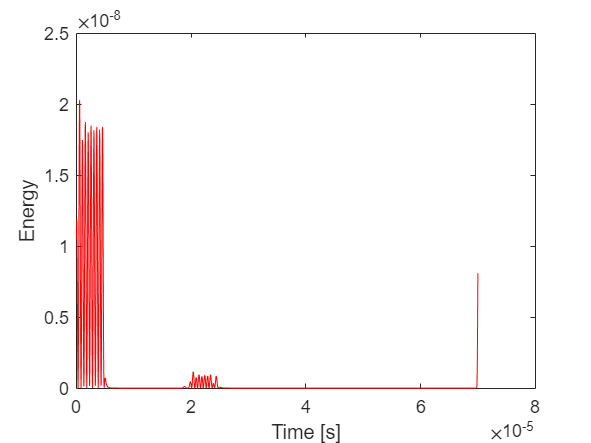

figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');




%original received signal
step(1)

ans = 930

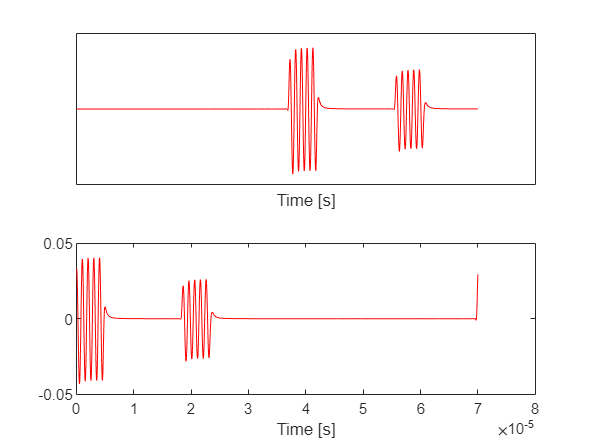

%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);


% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');


help kWaveGrid

 kWaveGrid Class definition for k-Wave grid.
 
  DESCRIPTION:
      kWaveGrid is the grid class used across the k-Wave Toolbox. An object
      of the kWaveGrid class contains the grid coordinates and wavenumber
      matrices used within the simulation and reconstruction functions in
      k-Wave. The grid matrices are indexed as: (x, 1) in 1D; (x, y) in
      2D; and (x, y, z) in 3D. The grid is assumed to be a regularly spaced
      Cartesian grid, with grid spacing given by dx, dy, dz (typically the
      grid spacing in each direction is constant). 
 
  USAGE:
      kgrid = kWaveGrid(Nx, dx)
      kgrid = kWaveGrid(Nx, dx, Ny, dy)
      kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz)
 
  INPUTS:
      Nx, Ny, Nz      - number of grid points in each Cartesian direction
      dx, dy, dz      - grid point spacing in each Cartesian direction [m]
 
  OUTPUTS:
      kgrid           - 